# Planteamiento de la cinemática inversa de la postura para un robot 4R

**Resumen**

Un robot de 4R tiene cuatro articulaciones rotacionales (o DOF, Degrees of Freedom), lo que significa que tiene 4 variables que deben ser resueltas para encontrar la posición de su efector final (manipulador o herramienta). Los eslabones están conectados de forma serial, y el objetivo es calcular los ángulos de las articulaciones a partir de las coordenadas deseadas de la herramienta (x, y, z).

El modelo cinemático inverso de la postura calcula los ángulos geométricos de las articulaciones del robot (cintura, hombro, codo y muñeca) a partir del vector de postura deseada para el efector final.

**Planteamiento de las variables**

Las variables que describen la cinemática de un robot de 4R son:

- **L1, L2, L3**: Longitudes de los tres primeros eslabones del robot.

- **x4, y4, z4**: Coordenadas de la posición deseada del efector final (herramienta).

- **theta1, theta2, theta3, theta4**: Ángulos de las articulaciones que queremos encontrar.

El planteamiento se desarrolla con base en la *Configuración de sistemas de referencia en un robot 4R*.

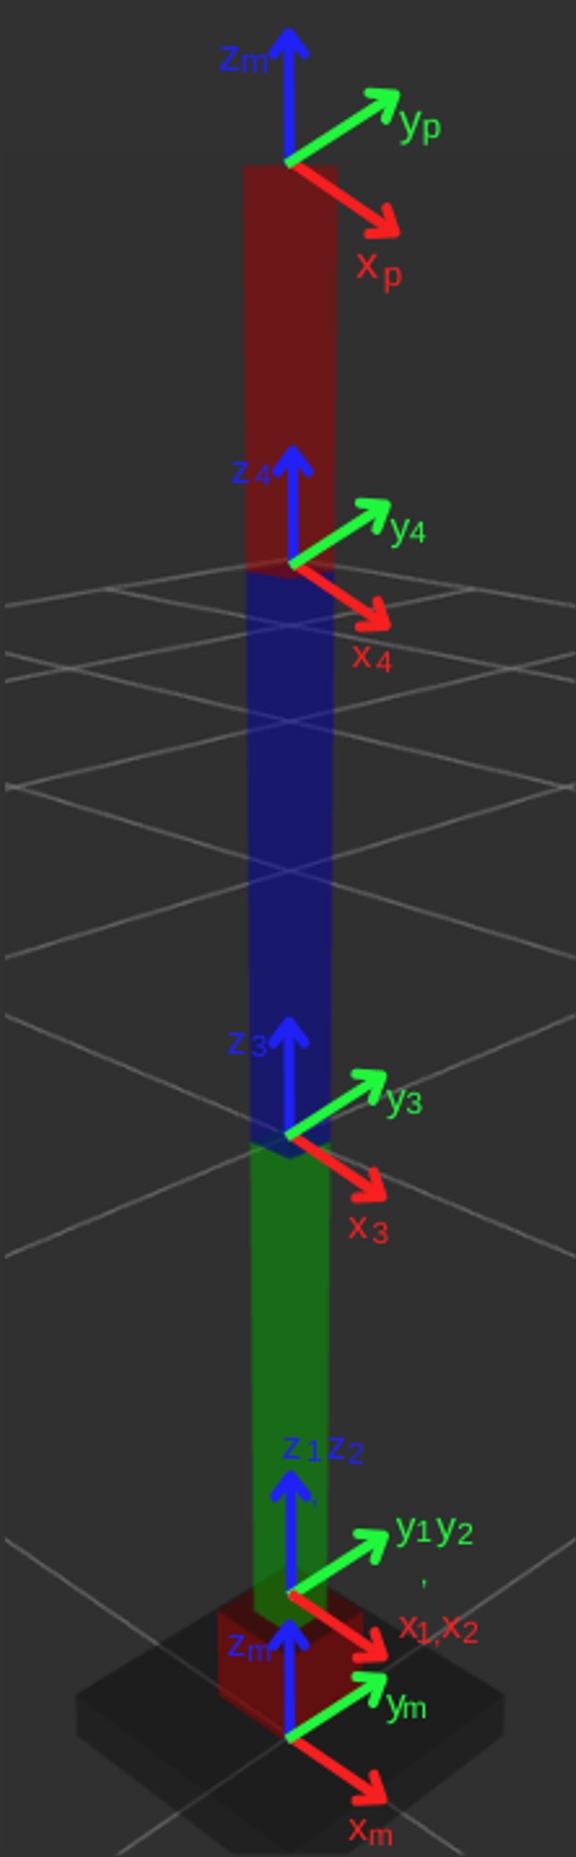

**Cálculo de la primera articulación (θ1�)**

En el modelo cinemático inverso de la postura, la posición y orientación del efector final se definen a través del vector de postura deseada.

syms x_0_p y_0_p z_0_p psi_0_p theta_0_p phi_0_p
xi_0_P = [x_0_p; y_0_p; z_0_p; psi_0_p; theta_0_p; phi_0_p]

$$xi\_0\_P = \left(\begin{array}{c} x_{0,p}\\ y_{0,p}\\ z_{0,p}\\ \psi_{0,p}\\ \theta_{0,p}\\ \varphi_{0,p} \end{array}\right)$$

A partir del vector de postura deseada del efector final, se obtiene la matriz de rotación ${}^0R_p$.

syms R_0_p(psi_0_p, theta_0_p, phi_0_p)
R_0_p(psi_0_p, theta_0_p, phi_0_p) = [cos(phi_0_p)*cos(theta_0_p) cos(phi_0_p)*sin(theta_0_p)*sin(psi_0_p)-sin(phi_0_p)*cos(psi_0_p) sin(phi_0_p)*sin(psi_0_p)+cos(phi_0_p)*sin(theta_0_p)*cos(psi_0_p); sin(phi_0_p)*cos(theta_0_p) cos(phi_0_p)*cos(psi_0_p)+sin(phi_0_p)*sin(theta_0_p)*sin(psi_0_p) sin(phi_0_p)*sin(theta_0_p)*cos(psi_0_p)-cos(phi_0_p)*sin(psi_0_p); -sin(theta_0_p) cos(theta_0_p)*sin(psi_0_p) cos(theta_0_p)*cos(psi_0_p)]

$$R\_0\_p(psi\_0\_p, theta\_0\_p, phi\_0\_p) = \left(\begin{array}{ccc} \cos\left(\varphi_{0,p}\right)\,\cos\left(\theta_{0,p}\right) & \cos\left(\varphi_{0,p}\right)\,\sin\left(\psi_{0,p}\right)\,\sin\left(\theta_{0,p}\right)-\cos\left(\psi_{0,p}\right)\,\sin\left(\varphi_{0,p}\right) & \sin\left(\varphi_{0,p}\right)\,\sin\left(\psi_{0,p}\right)+\cos\left(\varphi_{0,p}\right)\,\cos\left(\psi_{0,p}\right)\,\sin\left(\theta_{0,p}\right)\\ \cos\left(\theta_{0,p}\right)\,\sin\left(\varphi_{0,p}\right) & \cos\left(\varphi_{0,p}\right)\,\cos\left(\psi_{0,p}\right)+\sin\left(\varphi_{0,p}\right)\,\sin\left(\psi_{0,p}\right)\,\sin\left(\theta_{0,p}\right) & \cos\left(\psi_{0,p}\right)\,\sin\left(\varphi_{0,p}\right)\,\sin\left(\theta_{0,p}\right)-\cos\left(\varphi_{0,p}\right)\,\sin\left(\psi_{0,p}\right)\\ -\sin\left(\theta_{0,p}\right) & \cos\left(\theta_{0,p}\right)\,\sin\left(\psi_{0,p}\right) & \cos\left(\psi_{0,p}\right)\,\cos\left(\theta_{0,p}\right) \end{array}\right)$$

El desacoplamiento de la cinemática simplifica el desarrollo y la solución del modelo. Para ello, se establece la relación entre los vectores v1 y v2�. Dado que v1� es colineal con v2�, y este último corresponde a la tercera columna de la matriz de rotación.

syms P_0_p P_4_p L_3 z_0_4
P_4_p = P_0_p - L_3*z_0_4

$$P\_4\_p = P_{0,p}-L_{3}\,z_{0,4}$$

La primera articulación (theta1) se determina por la posición del efector final en el plano XY. Esto se calcula usando la **función atan2**, que toma en cuenta las coordenadas $X$  y $Y$ para obtener el ángulo en el plano:

theta_0_1 = atan2(y_0_p,x_0_p)

$$theta\_0\_1 = \text{atan2}\left(y_{0,p},x_{0,p}\right)$$

Los ángulos ${}{\theta }_2$, ${}{\theta }_3$ y ${}{\theta }_4$, y se determinan utilizando las propiedades geométricas.

El ángulo correspondiente al hombro se define a partir de la relación entre los ángulos y . Estos ángulos se describen tomando como referencia el vector , cuya magnitud sirve para representarlos.

syms a x_0_4 y_0_4 L_0
a = sqrt((x_0_4)^2+(y_0_4)^2+(x_0_4-L_0)^2)

$$a = \sqrt{{x_{0,4}}^{2}+{y_{0,4}}^{2}+{\left(L_{0}-x_{0,4}\right)}^{2}}$$

% Transformación homogenea
syms T_i_j(x_i_j, y_i_j, z_i_j, gamma_i_j, beta_i_j, alpha_i_j)
T_i_j(x_i_j, y_i_j, z_i_j, gamma_i_j, beta_i_j, alpha_i_j) = [cos(alpha_i_j)*cos(beta_i_j) cos(alpha_i_j)*sin(beta_i_j)*sin(gamma_i_j)-sin(alpha_i_j)*cos(gamma_i_j) sin(alpha_i_j)*sin(gamma_i_j)+cos(alpha_i_j)*sin(beta_i_j)*cos(gamma_i_j) x_i_j; sin(alpha_i_j)*cos(beta_i_j) cos(alpha_i_j)*cos(gamma_i_j)+sin(alpha_i_j)*sin(beta_i_j)*sin(gamma_i_j) sin(alpha_i_j)*sin(beta_i_j)*cos(gamma_i_j)-cos(alpha_i_j)*sin(gamma_i_j) y_i_j; -sin(beta_i_j) cos(beta_i_j)*sin(gamma_i_j) cos(beta_i_j)*cos(gamma_i_j) z_i_j; 0 0 0 1]

$$T\_i\_j(x\_i\_j, y\_i\_j, z\_i\_j, gamma\_i\_j, beta\_i\_j, alpha\_i\_j) = \left(\begin{array}{cccc} \cos\left(\alpha_{i,j}\right)\,\cos\left(\beta_{i,j}\right) & \cos\left(\alpha_{i,j}\right)\,\sin\left(\beta_{i,j}\right)\,\sin\left(\gamma_{i,j}\right)-\cos\left(\gamma_{i,j}\right)\,\sin\left(\alpha_{i,j}\right) & \sin\left(\alpha_{i,j}\right)\,\sin\left(\gamma_{i,j}\right)+\cos\left(\alpha_{i,j}\right)\,\cos\left(\gamma_{i,j}\right)\,\sin\left(\beta_{i,j}\right) & x_{i,j}\\ \cos\left(\beta_{i,j}\right)\,\sin\left(\alpha_{i,j}\right) & \cos\left(\alpha_{i,j}\right)\,\cos\left(\gamma_{i,j}\right)+\sin\left(\alpha_{i,j}\right)\,\sin\left(\beta_{i,j}\right)\,\sin\left(\gamma_{i,j}\right) & \cos\left(\gamma_{i,j}\right)\,\sin\left(\alpha_{i,j}\right)\,\sin\left(\beta_{i,j}\right)-\cos\left(\alpha_{i,j}\right)\,\sin\left(\gamma_{i,j}\right) & y_{i,j}\\ -\sin\left(\beta_{i,j}\right) & \cos\left(\beta_{i,j}\right)\,\sin\left(\gamma_{i,j}\right) & \cos\left(\beta_{i,j}\right)\,\cos\left(\gamma_{i,j}\right) & z_{i,j}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


syms T_2_3 z_2_3 theta_2_3
T_2_3 = T_i_j(0, 0, z_2_3, 0, theta_2_3, 0)

$$T\_2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{2,3}\right) & 0 & \sin\left(\theta_{2,3}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{2,3}\right) & 0 & \cos\left(\theta_{2,3}\right) & z_{2,3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


syms L_1 L_2
a = sqrt((L_1+L_2*cos(theta_2_3))^2+(L_2*sin(theta_2_3))^2)

$$a = \sqrt{{L_{2}}^{2}\,{\sin\left(\theta_{2,3}\right)}^{2}+{\left(L_{1}+L_{2}\,\cos\left(\theta_{2,3}\right)\right)}^{2}}$$

De esta forma, el ángulo $\varepsilon$ formado entre el vector unitario ${\hat{z} }_1$ y el vector $\bar{a}$ se define:

syms P_0_p P_4_p L_3 z_0_4
P_4_p = P_0_p - L_3*z_0_4

$$P\_4\_p = P_{0,p}-L_{3}\,z_{0,4}$$


syms epsilon 
epsilon = atan2(sqrt((x_0_4)^2+(y_0_4)^2),z_0_4-L_0)

$$epsilon = \text{atan2}\left(\sqrt{{x_{0,4}}^{2}+{y_{0,4}}^{2}},z_{0,4}-L_{0}\right)$$

De esta forma, el ángulo $\alpha$ formado entre el vector $L_1$ y el vector $\bar{a}$ se define:

syms alpha 
alpha = atan2(L_2*sin(theta_2_3),L_1+L_2*cos(theta_2_3))

$$alpha = \text{atan2}\left(L_{2}\,\sin\left(\theta_{2,3}\right),L_{1}+L_{2}\,\cos\left(\theta_{2,3}\right)\right)$$

theta_1_2 = epsilon - alpha

$$theta\_1\_2 = -\text{atan2}\left(L_{2}\,\sin\left(\theta_{2,3}\right),L_{1}+L_{2}\,\cos\left(\theta_{2,3}\right)\right)+\text{atan2}\left(\sqrt{{x_{0,4}}^{2}+{y_{0,4}}^{2}},z_{0,4}-L_{0}\right)$$

El angulo asociado al codo se obtiene de la ley de cosenos planteada a partir del vector $\bar{a}$.

theta_2_3 = acos(((x_0_4)^2+(y_0_4)^2+(L_0-z_0_4)^2)/(2*L_1*L_2))

$$theta\_2\_3 = \mathrm{acos}\left(\frac{{x_{0,4}}^{2}+{y_{0,4}}^{2}+{\left(L_{0}-z_{0,4}\right)}^{2}}{2\,L_{1}\,L_{2}}\right)$$

El ángulo asociado a la muñeca se obtiene descomponiendo la matriz de rotación${}^0R_p$. La rotación total desde el sistema inercial incluye la rotación $R_z$ con el ángulo${}^0{\theta }_1$, la rotación $R_y$ con la suma de los ángulos${}^1{\theta }_2$y${}^2{\theta }_3$, y la rotación${}^3R_p$ del efector final. Al despejar esta última, se obtiene ${\left(R_z R_y \right)}^T {}^0R_p$:

syms T_3_4 z_3_4 theta_3_4
T_3_4 = T_i_j(0, 0, z_3_4, 0, theta_3_4, 0)

$$T\_3\_4 = \left(\begin{array}{cccc} \cos\left(\theta_{3,4}\right) & 0 & \sin\left(\theta_{3,4}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{3,4}\right) & 0 & \cos\left(\theta_{3,4}\right) & z_{3,4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

syms theta_dot theta_dot_0_1 theta_dot_1_2 theta_dot_2_3 theta_dot_3_4
theta_dot = [theta_dot_0_1; theta_dot_1_2; theta_dot_2_3; theta_dot_3_4]

$$theta\_dot = \left(\begin{array}{c} {\dot{\theta }}_{0,1}\\ {\dot{\theta }}_{1,2}\\ {\dot{\theta }}_{2,3}\\ {\dot{\theta }}_{3,4} \end{array}\right)$$

R_3_p = [cos(theta_3_4) 0 sin(theta_3_4); 0 1 0; -sin(theta_3_4) 0 cos(theta_dot_3_4)]

$$R\_3\_p = \left(\begin{array}{ccc} \cos\left(\theta_{3,4}\right) & 0 & \sin\left(\theta_{3,4}\right)\\ 0 & 1 & 0\\ -\sin\left(\theta_{3,4}\right) & 0 & \cos\left({\dot{\theta }}_{3,4}\right) \end{array}\right)$$

De esta forma, el ángulo se obtiene del primer elemento de la matriz de rotación${}^3R_p$:

theta_3_4 = acos(R_3_p(1,1))

$$theta\_3\_4 = \mathrm{acos}\left(\cos\left(\theta_{3,4}\right)\right)$$